# Comparaison to bird radar.

## Loading files

clear all; addpath('./functions/'); 
load('../1-Cleaning/data/dc_corr.mat'); 
load('../1-Cleaning/data/sunrisesunset_grid.mat')
load('../2-Inference/data/Density_inference.mat');

dclat = [dc.lat]'; dclon = [dc.lon]'; dcname={dc.name};
clear dc

## Set-up the information for the estimation

Grid and time

pt.lat=[50.884889, 47.126356];
pt.lon=[2.544694, 8.193466];
pt.time = (start_date:1/24/4:end_date)';
pt.atime=unique(round(datenum(pt.time)));
[~,pt.dateradar] = min((bsxfun(@minus,datenum(pt.time),pt.atime')).^2,[],2);

pt.nl=numel(pt.lat);
pt.nt=numel(pt.time);
pt.nat=numel(pt.atime);

pt.time2D=repmat(pt.time,1,2);

Sunrise and sunset

pt.sunrise = nan(pt.nt,pt.nl);
pt.sunset = pt.sunrise;
for i_t=2:numel(tim_d)
    id = pt.time>tim_d(i_t)-1 & pt.time<=tim_d(i_t);
    
    F=griddedInterpolant({lat_d,lon_d},sunrs_e(:,:,i_t-1));
    pt.sunset(id,:)=repmat(F(pt.lat,pt.lon),sum(id),1);
    
    F=griddedInterpolant({lat_d,lon_d},sunrs_b(:,:,i_t));
    pt.sunrise(id,:)=repmat(F(pt.lat,pt.lon),sum(id),1);
end

Score time of night

pt.NNT = (datenum(pt.time2D)-mean(cat(3,pt.sunrise,pt.sunset),3)) ./ (pt.sunrise-pt.sunset)*2;

Mask of the day

pt.mask_day =  pt.NNT>-1 & pt.NNT<1;

Clear the masking variable

clear sunrs_b sunrs_e tim_d lat_d lon_d F 

## Kriging the amplitude $A\left(t,\mathit{\mathbf{s}}\right)$

Covariance matrix of weather radars

Dtime=squareform(pdist(ampli.T(~ampli.isnan)));
Ddist=squareform(pdist([dclat(ampli.R(~ampli.isnan)) dclon(ampli.R(~ampli.isnan))],@lldistkm));

Caa = ampli.cov.C(Ddist,Dtime);

Cross-covariance matrix of weather /bird radars

Ddist_sm = pdist2([dclat dclon] ,[pt.lat(:) pt.lon(:)], @lldistkm);
tmp1 = repmat(Ddist_sm(:,1),1,pt.nat);
tmp2 = repmat(Ddist_sm(:,2),1,pt.nat);
Ddist=[ repmat(tmp1(~ampli.isnan),1,pt.nat) repmat(tmp2(~ampli.isnan),1,pt.nat)];
tmp=repmat(pt.atime',numel(ampli.r),1);
Dtime = pdist2(tmp(~ampli.isnan), repmat(pt.atime, pt.nl, 1));

Cab = ampli.cov.C(Ddist,Dtime);

Solve the Kriging system

Lambda = Caa \ Cab;

 Compute the estimate and variance

ptampli.An_est = reshape(Lambda' * ampli.An,pt.nat,pt.nl);
ptampli.An_sig = reshape(sqrt(sum(ampli.cov.parm(1:3)) - diag(Lambda' * Cab)), pt.nat, pt.nl);

Add the trend

ptampli.A_est = ptampli.An_est+repmat(pt.lat,pt.nat,1)*ampli.w(2)+ampli.w(1);
ptampli.A_sig = ptampli.An_sig;

Figure

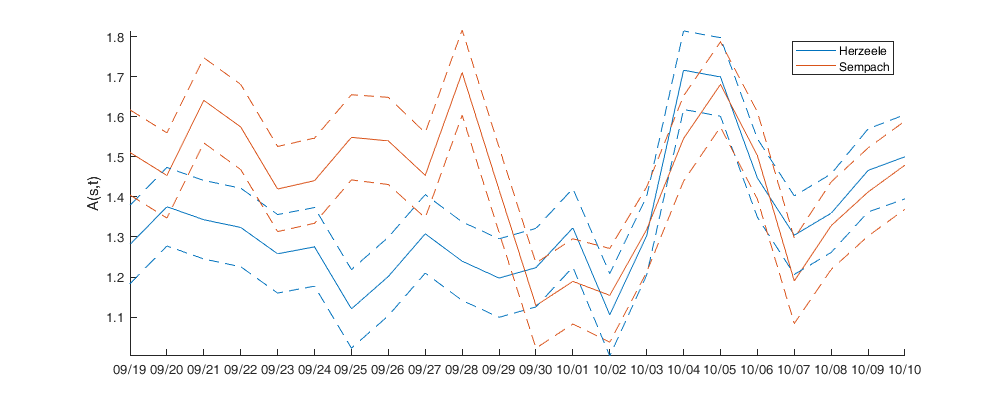

figure('position',[0 0 1000 400]); hold on;
plot(pt.atime, ptampli.A_est);ax = gca; ax.ColorOrderIndex = 1;
plot(pt.atime, ptampli.A_est+ptampli.A_sig,'--');ax = gca; ax.ColorOrderIndex = 1;
plot(pt.atime, ptampli.A_est-ptampli.A_sig,'--')
datetick('x'); axis tight; legend('Herzeele','Sempach'); ylabel('A(s,t)')

## Kriging the residual $R\left(t,\mathit{\mathbf{s}}\right)$

Covariance matrix of weather radar data 

Ddist_sq = squareform(pdist([dclat dclon], @lldistkm));
D=table();
for i_t=1:numel(ampli.t)
    id = find(data.day==i_t);
    d = table();
    d.Ddist = reshape(Ddist_sq(data.radar(id),data.radar(id)),[],1);
    d.Dtime = reshape(squareform(pdist(data.time(id))),[],1);
    d.Did1 = repmat(id,numel(id),1);
    d.Did2 = repelem(id,numel(id));
    D=[D ; d];
end
Caa = sparse(D.Did1,D.Did2, res.cov.C(D.Ddist, D.Dtime));

Distance matrix of bird / weather radar 

Ddist_sm = pdist2([dclat dclon] ,[pt.lat(:) pt.lon(:)], @lldistkm);
Dtime = pdist2(data.time, datenum(pt.time2D(pt.mask_day)));
Ddist = Ddist_sm(data.radar,[ones(1,sum(pt.mask_day(:,1))) 2*ones(1,sum(pt.mask_day(:,2)))]);

Cross-covariance

Cab = res.cov.C(Ddist,Dtime);

Solve the Kriging system

Lambda = Caa\Cab;

Compute the estimate and variance

ptres.Rn_est = Lambda' * res.Rn;
ptres.Rn_sig = sqrt(sum(res.cov.parm(1:3)) - diag(Lambda'*Cab));

Adding the trend

ptres.R_est=nan(pt.nt,pt.nl); ptres.R_sig=nan(pt.nt,pt.nl);
ptres.R_est(pt.mask_day) = ptres.Rn_est .* sqrt(bsxfun(@power,pt.NNT(pt.mask_day),0:res.bpo)*res.b) + bsxfun(@power,pt.NNT(pt.mask_day),0:res.apo)*res.a;
ptres.R_sig(pt.mask_day) = sqrt(ptres.Rn_sig.^2 .* (bsxfun(@power,pt.NNT(pt.mask_day),0:res.bpo)*res.b));

Figure

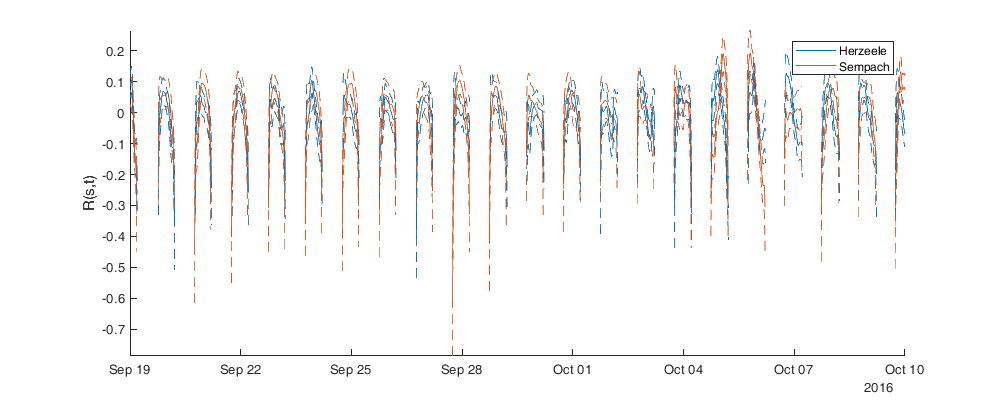

figure('position',[0 0 1000 400]); hold on; 
plot(pt.time, ptres.R_est);ax = gca; ax.ColorOrderIndex = 1;
plot(pt.time, ptres.R_est+ptres.R_sig,'--'); ax.ColorOrderIndex = 1;
plot(pt.time, ptres.R_est-ptres.R_sig,'--');
axis tight; legend('Herzeele','Sempach'); ylabel('R(s,t)');

## Reassemble amplitude and residual

pt.denst_est = ptampli.A_est(pt.dateradar,:) + ptres.R_est;
pt.denst_sig = sqrt(ptampli.A_sig(pt.dateradar).^2 + ptres.R_sig.^2);

Back-transform to normal space

pt.dens_est = (pt.denst_est).^(1/pow_a);

Compute the 10 and 90 quantile

pt.dens_q10 = ( pt.denst_est+norminv(.1).*pt.denst_sig ).^(1/pow_a);
pt.dens_q90 = ( pt.denst_est+norminv(.9).*pt.denst_sig ).^(1/pow_a);

Compute from -3 sigma to +3 sigma in original space (bird density)

nsig=7;
tmp = repmat(pt.denst_est,1,1,nsig) + reshape(pt.denst_sig(:)*(-3:3),pt.nt,pt.nl,nsig);
if any(tmp(:)<0)
    disp(['WARNING: Remove ' num2str(sum(tmp(:)<0)) ' value(s) because <0'])
    tmp(tmp<0)=nan;
end
pt.dens_sig =tmp.^(1/pow_a);

Figure

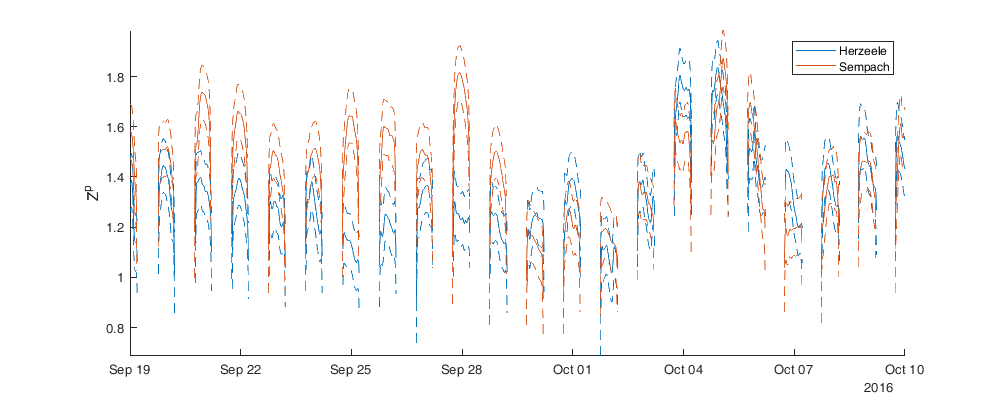

figure('position',[0 0 1000 400]); hold on; 
plot(pt.time, pt.denst_est);ax = gca; ax.ColorOrderIndex = 1;
plot(pt.time, pt.denst_est+pt.denst_sig,'--'); ax.ColorOrderIndex = 1;
plot(pt.time, pt.denst_est-pt.denst_sig,'--');
axis tight; legend('Herzeele','Sempach'); ylabel('Z^p');

## Simple Interpolation

Define the ratio distance/time for the interpolation (eg. 1 day = 1degree lat/lon). This value as been optimized with the data (see section below).

ratio_coord_time = 13;

Build interpolation

LAT = repmat(pt.lat,pt.nt,1);
LON = repmat(pt.lon,pt.nt,1);
interpo_nn = nan(pt.nt,pt.nl);
interpo_l = nan(pt.nt,pt.nl);
interpo_n = nan(pt.nt,pt.nl);

Fnn = scatteredInterpolant(data.lat,data.lon,data.time.*ratio_coord_time,data.dens,'nearest');
Fl = scatteredInterpolant(data.lat,data.lon,data.time.*ratio_coord_time,data.dens,'linear');
Fn = scatteredInterpolant(data.lat,data.lon,data.time.*ratio_coord_time,data.dens,'natural');

interpo_nn(pt.mask_day) = Fnn(LAT(pt.mask_day),LON(pt.mask_day),datenum(pt.time2D(pt.mask_day)).*ratio_coord_time) ;
interpo_l(pt.mask_day) = Fl(LAT(pt.mask_day),LON(pt.mask_day),datenum(pt.time2D(pt.mask_day)).*ratio_coord_time) ;
interpo_n(pt.mask_day) = Fn(LAT(pt.mask_day),LON(pt.mask_day),datenum(pt.time2D(pt.mask_day)).*ratio_coord_time);

## Import bird radar data

T_Herzeele = readtable('data/MTR_SorL_allBirds_hourly_Hrange50_1500asl_Hstep1450_inclFlight_13dBadj.csv','TreatAsEmpty','NA');
T_Herzeele(strcmp(T_Herzeele.OperMod,'L'),:)=[];
T_Herzeele.is_night = T_Herzeele.is_night==1;
T_Herzeele.dens = T_Herzeele.mtr/60/60./(T_Herzeele.meanSpeed./1000);
T_Herzeele.denstrans = T_Herzeele.dens.^pow_a;

T_Sem = readtable('data/SEM_MTR_allBirds_SeptOct2016_1h_2000m_inclFlight_sepPulse.csv','TreatAsEmpty','NA');
T_Sem(strcmp(T_Sem.oper_mod,'L'),:)=[];
T_Sem(strcmp(T_Sem.oper_mod,'M'),:)=[];
T_Sem.is_night = T_Sem.is_night==1;
T_Sem.dens = T_Sem.mtr/60/60./(T_Sem.meanSpeed./1000);
T_Sem.denstrans = T_Sem.dens.^pow_a;

for i_t=1:size(T_Herzeele,1)
    id = pt.time >= T_Herzeele.Tint(i_t) & pt.time < (T_Herzeele.Tint(i_t)+1/24);
    T_Herzeele.denst_est(i_t) = nanmean(pt.denst_est(id,1));
    T_Herzeele.denst_sig(i_t) = nanmean(pt.denst_sig(id,1));
    T_Herzeele.dens_est(i_t) = nanmean(pt.dens_est(id,1));
    T_Herzeele.dens_sig(i_t) = nanmean(pt.dens_sig(id,1));
    T_Herzeele.interpo_nn(i_t,:) = nanmean(interpo_nn(id,1));
    T_Herzeele.interpo_l(i_t,:) = nanmean(interpo_l(id,1));
    T_Herzeele.interpo_n(i_t,:) = nanmean(interpo_n(id,1));
end

for i_t=1:size(T_Sem,1)
    id = pt.time >= T_Sem.Tint(i_t) & pt.time < (T_Sem.Tint(i_t)+1/24);
    T_Sem.denst_est(i_t) = nanmean(pt.denst_est(id,2));
    T_Sem.denst_sig(i_t) = nanmean(pt.denst_sig(id,2));
    T_Sem.dens_est(i_t) = nanmean(pt.dens_est(id,2));
    T_Sem.dens_sig(i_t) = nanmean(pt.dens_sig(id,2));
    T_Sem.interpo_nn(i_t,:) = nanmean(interpo_nn(id,2));
    T_Sem.interpo_l(i_t,:) = nanmean(interpo_l(id,2));
    T_Sem.interpo_n(i_t,:) = nanmean(interpo_n(id,2));
end

Figure

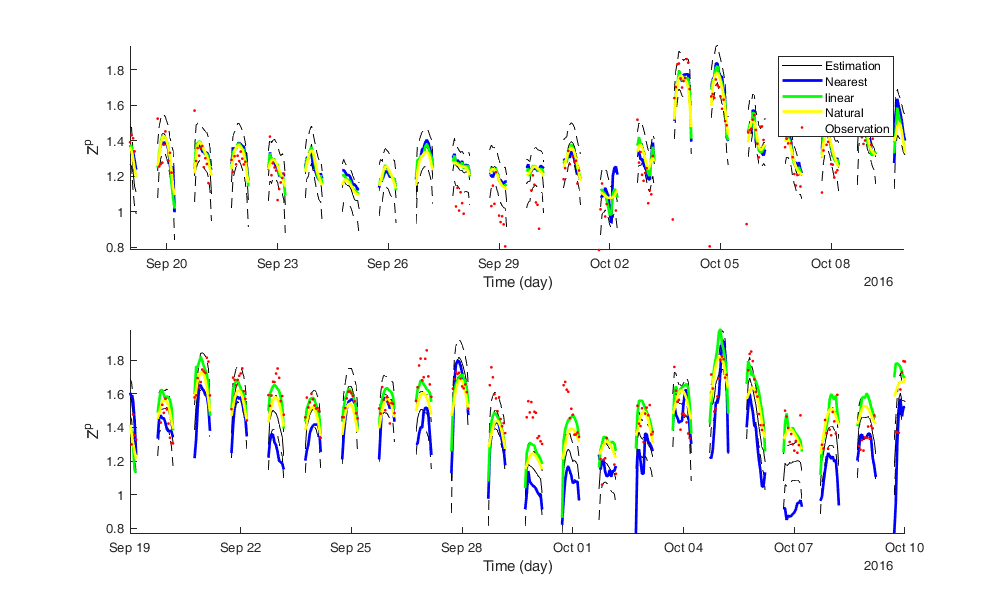

figure('position',[0 0 1000 600]); 
subplot(2,1,1);hold on;
plot(T_Herzeele.Tint, T_Herzeele.denst_est - T_Herzeele.denst_sig,'--k');
h1=plot(T_Herzeele.Tint, T_Herzeele.denst_est,'-k');
plot(T_Herzeele.Tint, T_Herzeele.denst_est + T_Herzeele.denst_sig,'--k');
h2=plot(T_Herzeele.Tint,T_Herzeele.interpo_nn.^pow_a,'-b','linewidth',2);
h3=plot(T_Herzeele.Tint,T_Herzeele.interpo_l.^pow_a,'-g','linewidth',2);
h4=plot(T_Herzeele.Tint,T_Herzeele.interpo_n.^pow_a,'-y','linewidth',2);
h5=plot(T_Herzeele.Tint(T_Herzeele.is_night),T_Herzeele.denstrans(T_Herzeele.is_night),'.r','linewidth',2);
legend([h1 h2 h3 h4 h5],'Estimation','Nearest','linear','Natural','Observation')
axis tight;xlim([start_date end_date]);xlabel('Time (day)'); ylabel('Z^p'); 
subplot(2,1,2);hold on;
plot(T_Sem.Tint, T_Sem.denst_est - T_Sem.denst_sig,'--k');
plot(T_Sem.Tint, T_Sem.denst_est,'-k');
plot(T_Sem.Tint, T_Sem.denst_est + T_Sem.denst_sig,'--k');
plot(T_Sem.Tint,T_Sem.interpo_nn.^pow_a,'-b','linewidth',2);
plot(T_Sem.Tint,T_Sem.interpo_l.^pow_a,'-g','linewidth',2);
plot(T_Sem.Tint,T_Sem.interpo_n.^pow_a,'-y','linewidth',2);
plot(T_Sem.Tint(T_Sem.is_night),T_Sem.denstrans(T_Sem.is_night),'.r','linewidth',2);
axis tight;xlim([start_date end_date]);xlabel('Time (day)'); ylabel('Z^p'); 

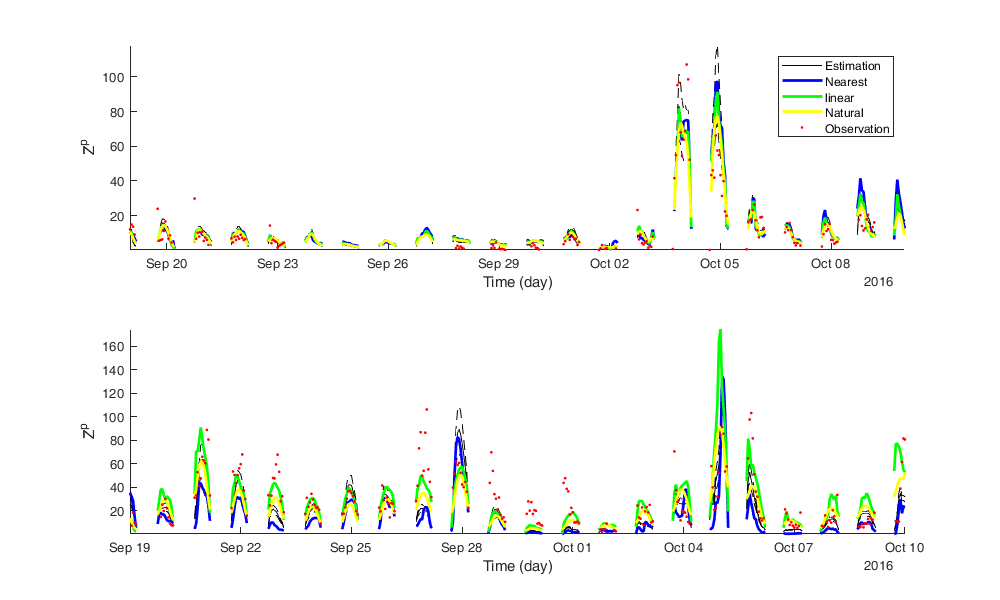

figure('position',[0 0 1000 600]); 
subplot(2,1,1);hold on;
plot(T_Herzeele.Tint, T_Herzeele.dens_est - T_Herzeele.dens_sig,'--k');
h1=plot(T_Herzeele.Tint, T_Herzeele.dens_est,'-k');
plot(T_Herzeele.Tint, T_Herzeele.dens_est + T_Herzeele.dens_sig,'--k');
h2=plot(T_Herzeele.Tint,T_Herzeele.interpo_nn,'-b','linewidth',2);
h3=plot(T_Herzeele.Tint,T_Herzeele.interpo_l,'-g','linewidth',2);
h4=plot(T_Herzeele.Tint,T_Herzeele.interpo_n,'-y','linewidth',2);
h5=plot(T_Herzeele.Tint(T_Herzeele.is_night),T_Herzeele.dens(T_Herzeele.is_night),'.r','linewidth',2);
axis tight;xlim([start_date end_date]);xlabel('Time (day)'); ylabel('Z^p'); 
legend([h1 h2 h3 h4 h5],'Estimation','Nearest','linear','Natural','Observation')
subplot(2,1,2);hold on;
plot(T_Sem.Tint, T_Sem.dens_est - T_Sem.dens_sig,'--k');
plot(T_Sem.Tint, T_Sem.dens_est,'-k');
plot(T_Sem.Tint, T_Sem.dens_est + T_Sem.dens_sig,'--k');
plot(T_Sem.Tint,T_Sem.interpo_nn,'-b','linewidth',2);
plot(T_Sem.Tint,T_Sem.interpo_l,'-g','linewidth',2);
plot(T_Sem.Tint,T_Sem.interpo_n,'-y','linewidth',2);
plot(T_Sem.Tint(T_Sem.is_night),T_Sem.dens(T_Sem.is_night),'.r','linewidth',2);
axis tight;xlim([start_date end_date]);xlabel('Time (day)'); ylabel('Z^p'); 

Score

pt_score.her.nee = (T_Herzeele.denst_est - T_Herzeele.denstrans) ./ T_Herzeele.denst_sig;
pt_score.her.nee_m = nanmean(pt_score.her.nee);
pt_score.her.nee_var = nanvar(pt_score.her.nee);
pt_score.her.n = sum(~isnan(pt_score.her.nee));
pt_score.her.rmse = sqrt(nanmean( (T_Herzeele.dens_est - T_Herzeele.dens).^2));
pt_score.her.rmse_nn = sqrt(nanmean( (T_Herzeele.interpo_nn - T_Herzeele.dens).^2));
pt_score.her.rmse_l = sqrt(nanmean( (T_Herzeele.interpo_l - T_Herzeele.dens).^2));
pt_score.her.rmse_n = sqrt(nanmean( (T_Herzeele.interpo_n - T_Herzeele.dens).^2));
pt_score.her

ans = struct with fields:
        nee: [1354×1 double]
      nee_m: 0.4852
    nee_var: 0.7719
          n: 168
       rmse: 9.2232
    rmse_nn: 9.7975
     rmse_l: 8.9119
     rmse_n: 8.9495


pt_score.sem.nee = (T_Sem.denst_est - T_Sem.denstrans) ./ T_Sem.denst_sig;
pt_score.sem.nee_m = nanmean(pt_score.sem.nee);
pt_score.sem.nee_var = nanvar(pt_score.sem.nee);
pt_score.sem.n = sum(~isnan(pt_score.sem.nee));
pt_score.sem.rmse = sqrt(nanmean( (T_Sem.dens_est - T_Sem.dens).^2));
pt_score.sem.rmse_nn = sqrt(nanmean( (T_Sem.interpo_nn - T_Sem.dens).^2));
pt_score.sem.rmse_l = sqrt(nanmean( (T_Sem.interpo_l - T_Sem.dens).^2));
pt_score.sem.rmse_n = sqrt(nanmean( (T_Sem.interpo_n - T_Sem.dens).^2));
pt_score.sem

ans = struct with fields:
        nee: [1463×1 double]
      nee_m: -0.6812
    nee_var: 1.4524
          n: 231
       rmse: 19.7303
    rmse_nn: 24.2551
     rmse_l: 21.6694
     rmse_n: 18.9431


## Save

save('data/Density_validationRadars','pt','ptampli','ptres','T_Herzeele','T_Sem','pt_score','-v7.3')

## Additional figure

Figures

figure('position',[0 0 1000 600]); 
subplot(2,1,1);hold on;
plot(pt.time, pt.denst_est(:,1) -3*pt.denst_sig(:,1),'--','Color',0.8*[1 1 1]);
plot(pt.time, pt.denst_est(:,1) - 2*pt.denst_sig(:,1),'--','Color',0.4*[1 1 1]);
plot(pt.time, pt.denst_est(:,1) - pt.denst_sig(:,1) ,'--','Color',0.2*[1 1 1]);
plot(pt.time, pt.denst_est(:,1),'-', 'Color',0*[1 1 1]);
plot(pt.time, pt.denst_est(:,1) + pt.denst_sig(:,1),'--','Color',0.2*[1 1 1]);
plot(pt.time, pt.denst_est(:,1) + 2*pt.denst_sig(:,1),'--','Color',0.4*[1 1 1]);
plot(pt.time, pt.denst_est(:,1) + 3*pt.denst_sig(:,1),'--','Color',0.8*[1 1 1]);
plot(T_Herzeele.Tint(T_Herzeele.is_night),T_Herzeele.denstrans(T_Herzeele.is_night),'.r','linewidth',2);
plot(datetime(data.time(data.radar==id_closest(1)),'ConvertFrom','datenum'),data.denst(data.radar==id_closest(1)),'-g','linewidth',2);
plot(pt.time,interpt(:,1),'-b','linewidth',2);
axis tight;xlim([start_date end_date]);xlabel('Time (day)'); ylabel('Z^p'); 
subplot(2,1,2);hold on;
plot(pt.time, pt.denst_est(:,2) -3*pt.denst_sig(:,2),'--','Color',0.8*[1 1 1]);
plot(pt.time, pt.denst_est(:,2) - 2*pt.denst_sig(:,2),'--','Color',0.4*[1 1 1]);
plot(pt.time, pt.denst_est(:,2) - pt.denst_sig(:,2) ,'--','Color',0.2*[1 1 1]);
plot(pt.time, pt.denst_est(:,2),'-', 'Color',0*[1 1 1]);
plot(pt.time, pt.denst_est(:,2) + pt.denst_sig(:,2),'--','Color',0.2*[1 1 1]);
plot(pt.time, pt.denst_est(:,2) + 2*pt.denst_sig(:,2),'--','Color',0.4*[1 1 1]);
plot(pt.time, pt.denst_est(:,2) + 3*pt.denst_sig(:,2),'--','Color',0.8*[1 1 1]);
plot(T_Sem.Tint(T_Sem.is_night),T_Sem.denstrans(T_Sem.is_night),'.r','linewidth',2);
plot(datetime(data.time(data.radar==id_closest(1)),'ConvertFrom','datenum'),data.denst(data.radar==id_closest(1)),'-g','linewidth',2);
plot(pt.time,interpt(:,2),'-b','linewidth',2);
axis tight;xlim([start_date end_date]);xlabel('Time (day)'); ylabel('Z^p'); 
figure('position',[0 0 1000 600]); hold on;
subplot(2,1,1);hold on;
plot(pt.time, pt.dens_sig(:,1,1),'--','Color',0.8*[1 1 1]);
plot(pt.time, pt.dens_sig(:,1,2),'--','Color',0.4*[1 1 1]);
plot(pt.time, pt.dens_sig(:,1,3),'--','Color',0.2*[1 1 1]);
plot(pt.time, pt.dens_sig(:,1,4),'-', 'Color',0*[1 1 1]);
plot(pt.time, pt.dens_sig(:,1,5),'--','Color',0.2*[1 1 1]);
plot(pt.time, pt.dens_sig(:,1,6),'--','Color',0.4*[1 1 1]);
plot(pt.time, pt.dens_sig(:,1,7),'--','Color',0.8*[1 1 1]);
plot(T_Herzeele.Tint(T_Herzeele.is_night),T_Herzeele.dens(T_Herzeele.is_night),'.r','linewidth',2);
plot(datetime(data.time(data.radar==id_closest(1)),'ConvertFrom','datenum'),data.dens(data.radar==id_closest(1)),'-g','linewidth',2);
plot(pt.time,interpo(:,1),'-b','linewidth',2);
xlim([start_date end_date]);xlabel('Time (day)'); ylabel('Bird/km^2')
subplot(2,1,2);hold on;
plot(pt.time, pt.dens_sig(:,2,1),'--','Color',0.8*[1 1 1]);
plot(pt.time, pt.dens_sig(:,2,2),'--','Color',0.4*[1 1 1]);
plot(pt.time, pt.dens_sig(:,2,3),'--','Color',0.2*[1 1 1]);
plot(pt.time, pt.dens_sig(:,2,4),'-', 'Color',0*[1 1 1]);
plot(pt.time, pt.dens_sig(:,2,5),'--','Color',0.2*[1 1 1]);
plot(pt.time, pt.dens_sig(:,2,6),'--','Color',0.4*[1 1 1]);
plot(pt.time, pt.dens_sig(:,2,7),'--','Color',0.8*[1 1 1]);
plot(T_Sem.Tint(T_Sem.is_night),T_Sem.dens(T_Sem.is_night),'.r','linewidth',2);
plot(datetime(data.time(data.radar==id_closest(1)),'ConvertFrom','datenum'),data.dens(data.radar==id_closest(1)),'-g','linewidth',2);
plot(pt.time,interpo(:,2),'-b','linewidth',2);
xlim([start_date end_date]);xlabel('Time (day)'); ylabel('Bird/km^2')